clc,clear
% 数据导入
% 地块面积向量
S = readmatrix("E:\数学建模比赛\CUMCM2024Problems\C题\附件1.xlsx",'Sheet','乡村的现有耕地');
S = S(:,3);
S = [S; S(27:54)];

% 2023年耕种情况
x0 = readmatrix("E:\数学建模比赛\自处理数据\初始值.xlsx");
x0 = x0(2:83,3:end);
x0(isnan(x0)) = 0;

% 售价矩阵
P =  readmatrix("E:\数学建模比赛\自处理数据\预期售价.xlsx");    
P = P(:,3:end);
P(isnan(P)) = 0;
%P = [P P P P P P P];

% 预期销售量矩阵
D = readmatrix("E:\数学建模比赛\自处理数据\预期销售量(1).xlsx");
D = D(:,2:end);
D(isnan(D)) = 0;
%D = [D D D D D D D];

% 预期亩产量
q = readmatrix("E:\数学建模比赛\自处理数据\预期亩产量.xlsx");      
q = q(:,3:end);
q(isnan(q)) = 0;
%q = [q q q q q q q];

% 预期亩成本
C = readmatrix("E:\数学建模比赛\自处理数据\预期每亩成本.xlsx");
C = C(:,3:end);
C(isnan(C)) = 0;


x1 = readmatrix("E:\数学建模比赛\自处理数据\3最坏情况的结果.xlsx",'Sheet','2024');

x2 = readmatrix("E:\数学建模比赛\自处理数据\3最坏情况的结果.xlsx",'Sheet','2025');

x3 = readmatrix("E:\数学建模比赛\自处理数据\3最坏情况的结果.xlsx",'Sheet','2026');

x4 = readmatrix("E:\数学建模比赛\自处理数据\3最坏情况的结果.xlsx",'Sheet','2027');

x5 = readmatrix("E:\数学建模比赛\自处理数据\3最坏情况的结果.xlsx",'Sheet','2028');

x6 = readmatrix("E:\数学建模比赛\自处理数据\3最坏情况的结果.xlsx",'Sheet','2029');

x7 = readmatrix("E:\数学建模比赛\自处理数据\3最坏情况的结果.xlsx",'Sheet','2030');

% 蒙特卡洛模拟10000次
M = [];
for i = 1:10000
    % 确定各种参数的变化
    % 小麦和玉米预期销售量的平均年增长率介于0.05~0.1之间
    % 均匀分布
    for i = 1:7
        r_D1(i) = (rand()+1)*0.05;
    end

    % 其他农作物的预期销售量相较于2023年有5%的上下浮动变化
    % 均匀分布
    for i = 1:7
        r_D2(i) = (rand()-0.5)*0.1;
    end

    % 农作物的亩产量每年会有10%的上下浮动
    % 均匀分布
    for i = 1:7
        r_q(i) = (rand()-0.5)*0.2;
    end

    % 农作物种植成本平均每年增长5%左右
    % 正态分布
    for i = 1:7
        r_C1(i) = randn()*0.003+0.05;
    end

    % 蔬菜平均每年增长5%左右
    % 正态分布
    for i = 1:7
        r_C2(i) = randn()*0.003+0.05;
    end

    % 食用菌除羊肚菌外销售价格大约每年下降1%~5%
    % 均匀分布
    for i = 1:7
        r_P1(i) = (4*rand()-5)*0.01;
    end


    % 羊肚菌销售价格每年下降幅度为5%
    r_P2 = [-0.05 -0.05 -0.05 -0.05 -0.05 -0.05 -0.05];               %确定的数


    % 确定7种变化在7年的最终变化情况
    % 小麦和玉米预期销售量的平均年增长率介于0.05~0.1之间
    Y_r_D1 = ones(7,7);
    for i = 1:7
        Y_r_D1(i,7:-1:(8-i)) = r_D1(1:i)+1;
    end
    Y_r_D1 = Y_r_D1(:,1).* Y_r_D1(:,2).*Y_r_D1(:,3).* Y_r_D1(:,4).* Y_r_D1(:,5).* Y_r_D1(:,6).* Y_r_D1(:,7);


    % 其他农作物的预期销售量相较于2023年有5%的上下浮动变化
    Y_r_D2 = r_D2'+1;

    % 农作物的亩产量每年会有10%的上下浮动
    Y_r_q = r_q'+1;

    % 农作物种植成本平均每年增长5%左右
    Y_r_C1 = ones(7,7);
    for i = 1:7
        Y_r_C1(i,7:-1:(8-i)) = r_C1(1:i)+1;
    end
    Y_r_C1 = Y_r_C1(:,1).* Y_r_C1(:,2).*Y_r_C1(:,3).* Y_r_C1(:,4).* Y_r_C1(:,5).* Y_r_C1(:,6).* Y_r_C1(:,7);

    % 蔬菜销售价格平均每年增长5%左右
    Y_r_C2 = ones(7,7);
    for i = 1:7
        Y_r_C2(i,7:-1:(8-i)) = r_C2(1:i)+1;
    end
    Y_r_C2 = Y_r_C2(:,1).* Y_r_C2(:,2).*Y_r_C2(:,3).* Y_r_C2(:,4).* Y_r_C2(:,5).* Y_r_C2(:,6).* Y_r_C2(:,7);

    % 食用菌除羊肚菌外销售价格大约每年下降1%~5%
    Y_r_P1 = ones(7,7);
    for i = 1:7
        Y_r_P1(i,7:-1:(8-i)) = r_P1(1:i)+1;
    end
    Y_r_P1= Y_r_P1(:,1).* Y_r_P1(:,2).*Y_r_P1(:,3).* Y_r_P1(:,4).* Y_r_P1(:,5).* Y_r_P1(:,6).* Y_r_P1(:,7);

    % 羊肚菌销售价格每年下降幅度为5%
    Y_r_P2 = ones(7,7);
    for i = 1:7
        Y_r_P2(i,7:-1:(8-i)) = r_P2(1:i)+1;
    end
    Y_r_P2 = Y_r_P2(:,1).* Y_r_P2(:,2).*Y_r_P2(:,3).* Y_r_P2(:,4).* Y_r_P2(:,5).* Y_r_P2(:,6).* Y_r_P2(:,7);


    % 计算每次模拟的结果
    R1 = calculateR4(x0, x1, 1, S, P, D, q, C, Y_r_D1, Y_r_D2, Y_r_q, Y_r_C1, Y_r_C2, Y_r_P1, Y_r_P2);
    R2 = calculateR4(x1, x2, 2, S, P, D, q, C, Y_r_D1, Y_r_D2, Y_r_q, Y_r_C1, Y_r_C2, Y_r_P1, Y_r_P2);
    R3 = calculateR4(x2, x3, 3, S, P, D, q, C, Y_r_D1, Y_r_D2, Y_r_q, Y_r_C1, Y_r_C2, Y_r_P1, Y_r_P2);
    R4 = calculateR4(x3, x4, 4, S, P, D, q, C, Y_r_D1, Y_r_D2, Y_r_q, Y_r_C1, Y_r_C2, Y_r_P1, Y_r_P2);
    R5 = calculateR4(x4, x5, 5, S, P, D, q, C, Y_r_D1, Y_r_D2, Y_r_q, Y_r_C1, Y_r_C2, Y_r_P1, Y_r_P2);
    R6 = calculateR4(x5, x6, 6, S, P, D, q, C, Y_r_D1, Y_r_D2, Y_r_q, Y_r_C1, Y_r_C2, Y_r_P1, Y_r_P2);
    R7 = calculateR4(x6, x7, 7, S, P, D, q, C, Y_r_D1, Y_r_D2, Y_r_q, Y_r_C1, Y_r_C2, Y_r_P1, Y_r_P2);

    R = R1+R2+R3+R4+R5+R6+R7;

    M = [M R];
end

s = std(M)

s = 1.2008e+06

m = mean(M)

m = 4.8044e+07

min_M = min(M)

min_M = 4.4107e+07

max_M = max(M)

max_M = 5.2446e+07

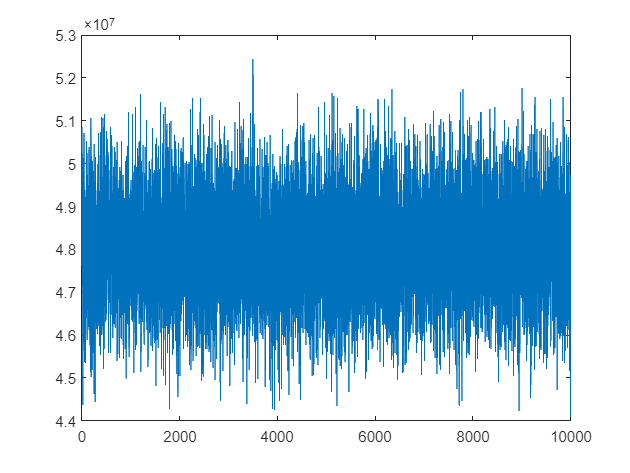


plot(1:10000,M)